# Modello Simulink, conversione C2D e modi di risposta

Dato il sistema LTI autonomo, a tempo continuo, descritto dalle equazioni di stato


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=&  -x_2(t) \\
\dot{x}_2(t) &=& +x_1(t)
\end{array} \right.$$


si chiede di:

- realizzare un modello Simulink che permetta di simulare il sistema e di visualizzare i risultati della simulazione in Matlab;

- scegliere 2 diverse condizioni iniziali per lo stato all'istante iniziale $t=0$ e simulare l'evoluzione dello stato per un intervallo di tempo pari a $15$ s;

- scegliere un opportuno periodo di campionamento ed ottenere una descrizione in equazioni di stato a tempo discreto in Matlab;

- della descrizione appena ottenuta determinare i modi di risposta.

clear;
close all;

t_sim = 15.0; % seconds
x_0_1 = 0;
x_0_2 = 0;

open("esercizio_simulink.slx");
sim_out = sim("esercizio_simulink.slx");
sim_data = sim_out.find("yout");

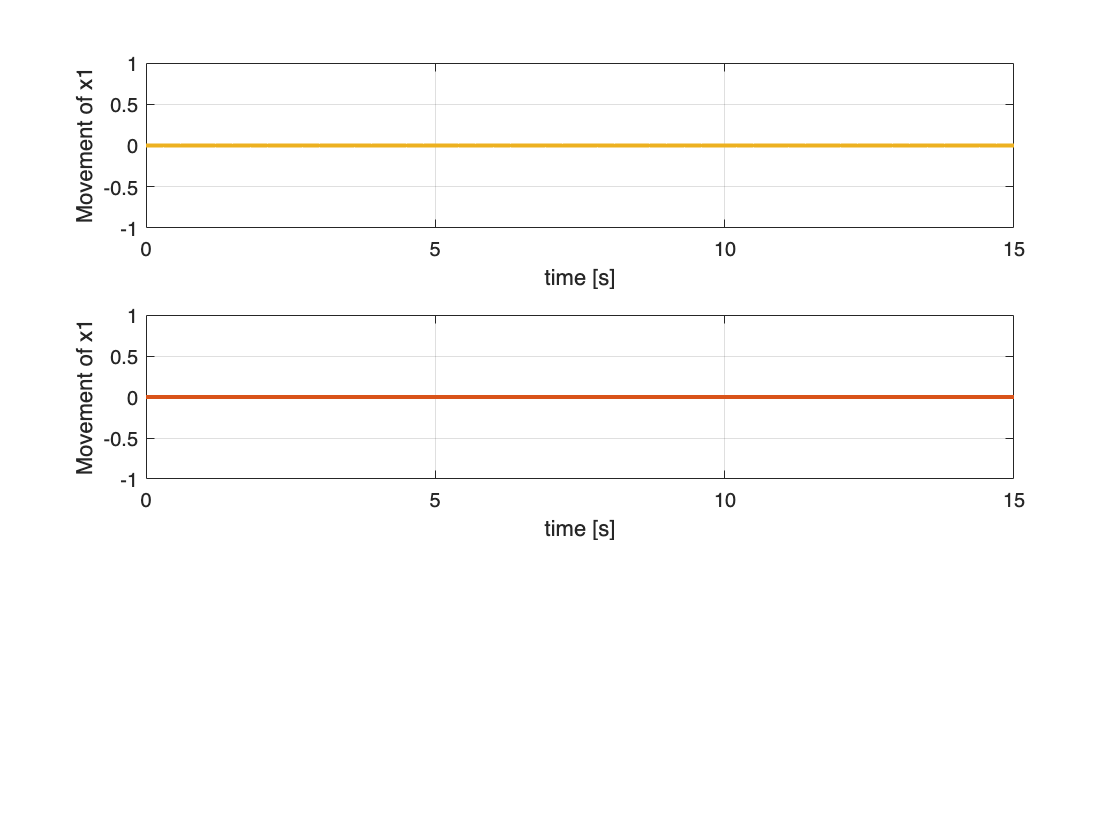

x1 = sim_data{1}.Values.Data;
x2 = sim_data{2}.Values.Data;
t_stamps = sim_out.tout;

subplot(3,1,1);
plot(t_stamps, x1, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]);
xlabel('time [s]');
ylabel('Movement of x1');
grid on;

subplot(3,1,2);
plot(t_stamps, x2, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]);
xlabel('time [s]');
ylabel('Movement of x1');
grid on;

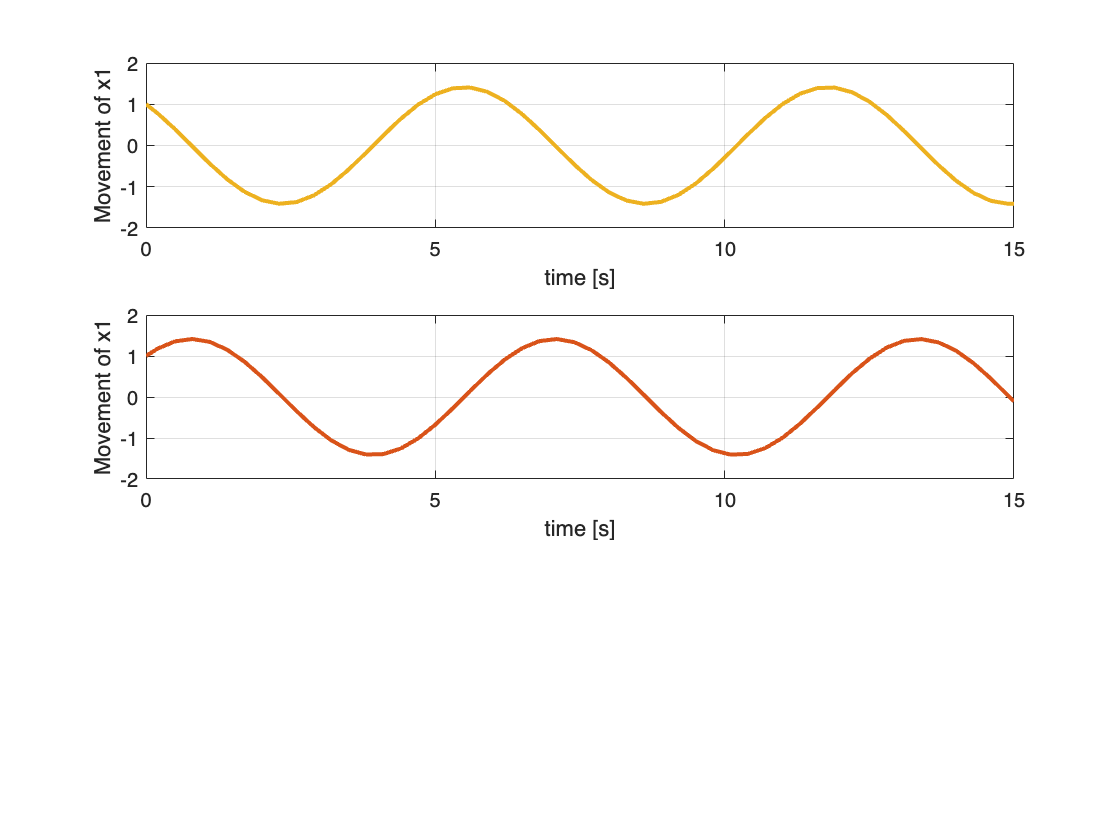

x_0_1 = 1;
x_0_2 = 1;
sim_out = sim("esercizio_simulink.slx");
sim_data = sim_out.find("yout");

x1 = sim_data{1}.Values.Data;
x2 = sim_data{2}.Values.Data;
t_stamps = sim_out.tout;


figure(1)
subplot(3,1,1);
plot(t_stamps, x1, 'LineWidth',2, 'Color',[0.9290 0.6940 0.1250]);
xlabel('time [s]');
ylabel('Movement of x1');
grid on;

subplot(3,1,2);
plot(t_stamps, x2, 'LineWidth',2, 'Color',[0.8500 0.3250 0.0980]);
xlabel('time [s]');
ylabel('Movement of x1');
grid on;

- scegliere un opportuno periodo di campionamento ed ottenere una descrizione in equazioni di stato a tempo discreto in Matlab;

%y = fft(x1);
%Ts = 10e-3;
%fs = 1/Ts;
%f = (0:length(y)-1)*fs/length(y);
%
%figure(2)
%subplot(1,1,1);
%plot(f, abs(y))
%grid on;

%[maxValue,indexMax] = max(abs(fft(x1-mean(x1))));
%frequency = indexMax * fs / L;

A = [0 -1; 1 0];
B = [0 0]';
C = [0 0];
D = 0;

eig(A)

ans =    0.0000 + 1.0000i
   0.0000 - 1.0000i


Since we know the eigenvalues and we know that the response are in the form $y = e^{\lambda*t} = e^{2 \pi f t} \Rightarrow  \lambda t = 2 \pi f t \Rightarrow f = \frac{1}{2 \pi}$ 

f_sig = 1 / (2 * pi)

f_sig = 0.1592

Hence, we need at least a frequency twice this high to have a good representation of the system.

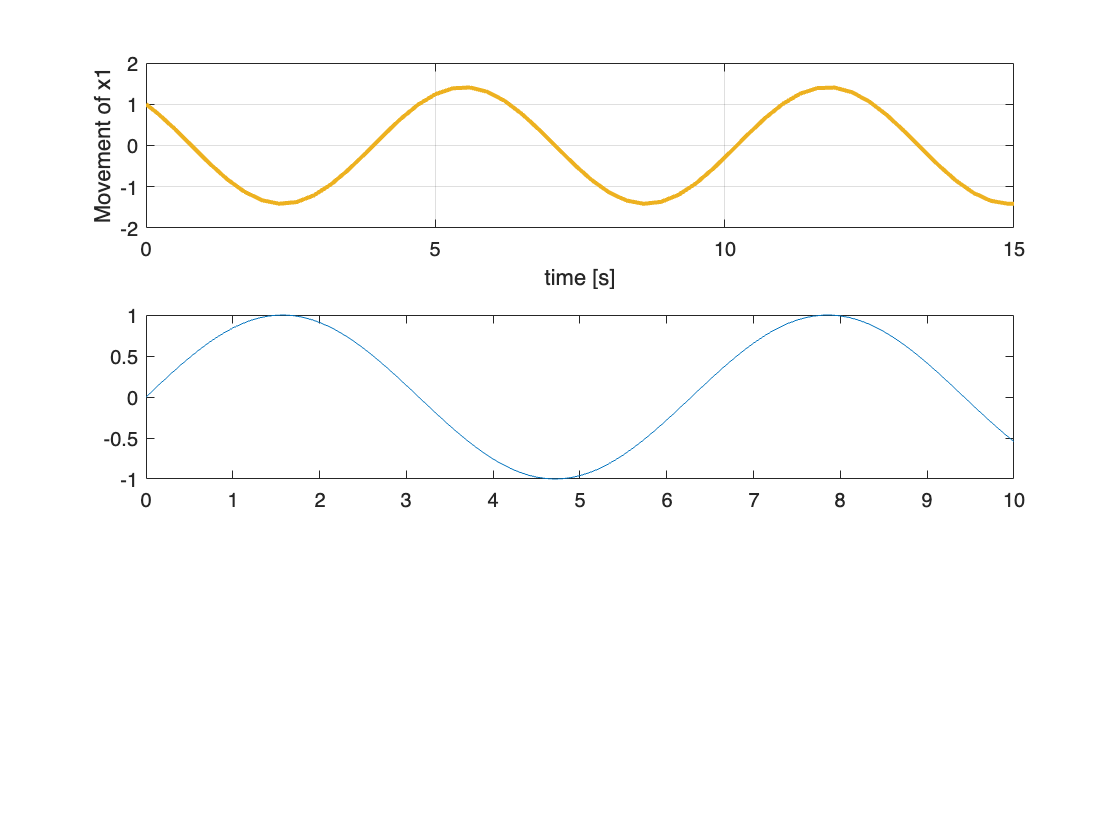

t = 0:0.1:10;
y = sin(2 * pi * f_sig * t);
plot(t, y);

This chart looks the same as the state movement we've seen before, so we can assume this frequency approximation is sufficiently good.

f_sampling = 2 * f_sig;
sysC = ss(A,B,C,D);
sysD = c2d(sysC,1); %1/f_sampling);

lambdas = eig(sysD.A)

lambdas =    0.5403 + 0.8415i
   0.5403 - 0.8415i


The eigenvalues we got from the discretization of the system, lay on the unitary circle. This means the system is stable (not asymptotically). This is coherent with what we've seen on the Simulink simulation: the sine wave is not getting dampened as time passes by, thus both systems are stable.

- della descrizione appena ottenuta determinare i modi di risposta.

To get the response modes, we cannot use the following formulas:

$A_1 = \lim_{z \to \lambda_1} (z - \lambda_1)(zI-A)^{-1}$, in case we have multiplicity = 1

$A_2 = \lim_{z \to \lambda_2} \frac{d}{dz} [(z-2)^2 (zI - A)^-1]$, in case we have multiplicity

since the limit function cannot operate in case we want to look the behavior as we are approaching a complex value.

There are two other methods available:

- left and right eigenvectors

- Jordan matrices

[rV, lambdas] = eig(sym(sysD.A));
lambdas = diag(lambdas);
% let's calculate an orthonormal left eigenvector matrix
lV = inv(rV);

% calculate the two matrices for the response modes
A1 = rV(:,1) * lV(1,:);
A2 = rV(:,2) * lV(2,:);

k = sym("k");
mode_1 = A1 * lambdas(1)^k

$$mode\_1 = \left(\begin{array}{cc} \frac{{\left(\frac{1216652631687587}{2251799813685248}-\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}}{2} & -\frac{{\left(\frac{1216652631687587}{2251799813685248}-\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}\,\mathrm{i}}{2}\\ \frac{{\left(\frac{1216652631687587}{2251799813685248}-\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}\,\mathrm{i}}{2} & \frac{{\left(\frac{1216652631687587}{2251799813685248}-\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}}{2} \end{array}\right)$$

mode_2 = A2 * lambdas(2)^k

$$mode\_2 = \left(\begin{array}{cc} \frac{{\left(\frac{1216652631687587}{2251799813685248}+\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}}{2} & \frac{{\left(\frac{1216652631687587}{2251799813685248}+\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}\,\mathrm{i}}{2}\\ -\frac{{\left(\frac{1216652631687587}{2251799813685248}+\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}\,\mathrm{i}}{2} & \frac{{\left(\frac{1216652631687587}{2251799813685248}+\frac{3789648413623927}{4503599627370496}\,\mathrm{i}\right)}^{k}}{2} \end{array}\right)$$

% [rV, ~] = eig(sysD.A); % the right eigenvectors
% [lV, ~] = eig(sysD.A'); 
% lV = lV'; % the right eigenvectors are row vectors
% shouldBeEyematrix = lV*rV
%% [rV, D, lV] = eig(sysD.A);
%% shouldBeEye = lV*rV;

[V, J] = jordan(sysD.A);
%%% inv(V) * sysD.A * V = J

k = sym("k");
A_sym = sym(sysD.A);
modes = inv(V) * A_sym^k * V